# 3주차 과제 — 블록선도, 상태공간, 선형화

**제어시스템설계** · 충남대학교 자율운항시스템공학과

문제는 **세 개**입니다.

- **1. 몸풀기** (쉬움 · 수업 중 10분 · 30점) — 블록선도 손으로 축약하기

- **2. 기본** (중간 · 40분 · 70점) — 진자 선형화가 몇 도까지 통하는가

- **3. 도전** (선택 · 가산점 10점) — 상태공간으로 바꿔 보기

**3번은 선택입니다.** 1번과 2번만 해도 만점입니다.

clc; close all;
s = tf('s');

## 1. 몸풀기 — 블록선도 축약

**강의노트 1절과 2절을 그대로 보면 됩니다.** 외울 것은 세 줄뿐입니다.

- **직렬** 이어 붙이면 곱한다 : $G_1 G_2$

- **병렬** 나란히 놓으면 더한다 : $G_1 + G_2$

- **되먹임** 루프를 닫으면 : $\frac{G}{1 + GH}$

오늘 축약할 구조입니다.

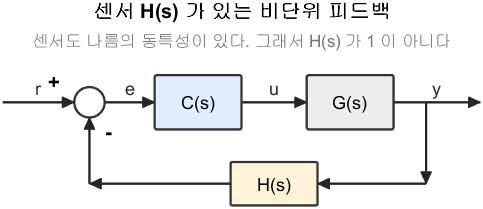

센서 H(s) 가 있는 비단위 피드백

**그림 파일** `loop_sensor.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_sensor')`

## 1-1. 손으로 먼저

값은 이렇습니다.


$$C(s) = 4, \qquad G(s) = \frac{1}{s+2}, \qquad H(s) = \frac{3}{s+3}$$


할 일 — 손으로 세 가지를 구하십시오 (계산은 짧습니다).

- 개루프 $L(s) = C\,G\,H$

- 폐루프 $T(s) = \frac{CG}{1 + CGH}$

- $T$ 의 **DC 이득** $T(0)$

힌트 : 분모를 정리하면 2차 다항식이 나옵니다.

## 1-2. MATLAB 으로 확인

`TODO` 두 줄만 채우십시오.

쓸 명령

- `feedback(A, B)` — $\frac{A}{1+AB}$ 를 만든다

- `minreal(...)` — 약분해서 깔끔하게 정리한다

C_ = 4;
G_ = 1/(s+2);
H_ = 3/(s+3);

L_ = NaN;    % TODO : C_*G_*H_ 로 개루프를 만드십시오
T_ = NaN;    % TODO : feedback(C_*G_, H_) 로 폐루프를 만드십시오

if isa(T_, 'tf')
    fprintf('개루프 L(s)\n');  minreal(L_)
    fprintf('폐루프 T(s)\n');  minreal(T_)
    fprintf('  T(0) = %.4f\n', dcgain(T_));
end

## 1-3. 답할 것 (두 문장이면 됩니다)

- 손으로 구한 $T(0)$ 과 MATLAB 값이 같은가?

- 이 센서는 $H(0) = 3/3 = 1$ 입니다. 그런데 센서가 고장 나서 $H(0) = 3$ 이 되었다면 $T(0)$ 은 커지는가 작아지는가? 한 줄로 이유를 쓰십시오 (계산해도 되고, 식만 보고 답해도 됩니다)

## 2. 기본 — 선형화가 몇 도까지 통하는가

**강의노트 8절부터 12절까지를 그대로 보면 됩니다.**

진자의 운동방정식에는 $\sin\theta$ 가 들어 있습니다.


$$m\,l^2\,\ddot{\theta} = -m\,g\,l\,\sin\theta + \tau$$


$\sin$ 은 곡선이라 우리 도구(전달함수)로 다룰 수 없습니다. 그래서 한 점 근처에서 **곧은 선으로 바꿔** 씁니다.


$$\sin\theta \approx \theta \qquad (\theta \text{ 가 작을 때})$$


그런데 "작다" 는 것이 몇 도까지인가? 그것을 직접 확인합니다.

## 2-1. 먼저 sin 과 직선을 겹쳐 그려 보기

코드는 다 되어 있습니다. 실행만 하면 됩니다.

th = linspace(-pi/2, pi/2, 400);
plot(rad2deg(th), sin(th), 'LineWidth', 2); hold on;
plot(rad2deg(th), th, 'LineWidth', 2);
grid on; xlabel('각도 [deg]'); ylabel('값');
legend('sin\theta (진짜)', '\theta (근사)', 'Location', 'southeast');
title('작은 각도에서는 두 선이 겹친다');

## 2-2. 오차를 표로

`TODO` 한 줄만 채우십시오.

상대오차의 정의는 이렇습니다.


$$\text{상대오차}[\%] = \frac{|\theta - \sin\theta|}{|\sin\theta|}\times 100$$


fprintf('\n  각도[deg]   sin(theta)    theta      상대오차[%%]\n');
fprintf('  ---------  -----------  ---------  -----------\n');
for deg = [1 5 10 20 30 45]
    rad = deg2rad(deg);
    err = NaN;    % TODO : 위 공식대로 상대오차를 계산하십시오
    fprintf('  %9d  %11.5f  %9.5f  %11.2f\n', deg, sin(rad), rad, err);
end

## 2-3. 답할 것 (한 문장)

- 오차를 $5\%$ 아래로 유지하려면 각도를 몇 도까지 써도 되는가? (표에서 읽으면 됩니다)

## 2-4. 매달린 진자와 거꾸로 선 진자

같은 진자인데 **어느 자리 근처에서 펴느냐**에 따라 결과가 완전히 달라집니다.

- $\theta = 0$ (아래로 매달림) 근처에서 펴면 : $\sin\theta \approx \theta$

- $\theta = \pi$ (거꾸로 섬) 근처에서 펴면 : $\sin\theta \approx -(\theta-\pi)$

부호 하나가 바뀝니다. 그 결과 극점이 어떻게 달라지는지 봅니다.

`TODO` 두 줄을 채우십시오. 힌트는 바로 위 부호입니다.

g_ = 9.81;  l_ = 0.3;

G_down = NaN;    % TODO : 1/(s^2 + g_/l_) 로 만드십시오  (매달린 진자)
G_up   = NaN;    % TODO : 1/(s^2 - g_/l_) 로 만드십시오  (거꾸로 선 진자)

if isa(G_down, 'tf') && isa(G_up, 'tf')
    fprintf('\n  매달린 진자   극점 : %s\n', mat2str(round(pole(G_down).', 3)));
    fprintf('  거꾸로 선 진자 극점 : %s\n', mat2str(round(pole(G_up).', 3)));

    tiledlayout(1,2,'TileSpacing','compact');
    nexttile
    plot(real(pole(G_down)), imag(pole(G_down)), 'bx', 'MarkerSize', 14, 'LineWidth', 2);
    hold on; xline(0,'k-'); yline(0,'k-'); grid on;
    xlim([-8 8]); ylim([-8 8]);
    xlabel('실수부'); ylabel('허수부'); title('매달린 진자 : 허수축 위');
    nexttile
    plot(real(pole(G_up)), imag(pole(G_up)), 'rx', 'MarkerSize', 14, 'LineWidth', 2);
    hold on; xline(0,'k-'); yline(0,'k-'); grid on;
    xlim([-8 8]); ylim([-8 8]);
    xlabel('실수부'); ylabel('허수부'); title('거꾸로 선 진자 : 하나가 우반면');
end

## 2-5. 답할 것 (두 문장)

- 두 경우의 극점 위치는 어떻게 다른가?

- 그래서 어느 쪽이 **제어가 필요한** 시스템인가? 왜인가?

## 3. 도전 (선택) — 상태공간으로 바꿔 보기

**이 문제는 선택입니다. 안 해도 만점입니다.** 가산점 10점입니다.

질량-스프링-댐퍼를 상태공간으로 바꿉니다.


$$m\ddot{x} + b\dot{x} + kx = F, \qquad m=1,\; b=0.2,\; k=1$$


상태를 이렇게 잡습니다.


$$x_1 = x \;(\text{위치}), \qquad x_2 = \dot{x}\;(\text{속도})$$


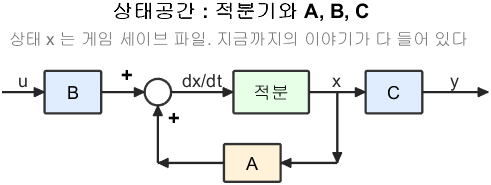

상태공간 : 적분기와 A, B, C

**그림 파일** `loop_statespace.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_statespace')`

할 일

- $\dot{x}_1$ 과 $\dot{x}_2$ 를 $x_1, x_2, F$ 로 손으로 쓰라

- 그것을 $A, B, C, D$ 행렬로 정리하라 (출력은 위치 $x$)

- `ss(A,B,C,D)` 로 만들고 `tf(...)` 로 전달함수로 바꿔 2주차에서 구한 $1/(s^2+0.2s+1)$ 과 같은지 확인하라

힌트

- $\dot{x}_1 = x_2$ 는 정의 그 자체입니다

- $\dot{x}_2$ 는 운동방정식을 $\ddot{x}$ 에 대해 푼 것입니다

TODO : 여기에 코드를 작성하십시오

## 채점 기준

- **1. 몸풀기** 30점 — 손 축약과 MATLAB 확인이 일치하는가

- **2. 기본** 70점 — 오차 표, 두 진자의 극점, 네 질문에 답했는가

- **3. 도전** 가산점 10점

감점 사항 (세 가지뿐입니다)

- 축 이름이나 범례가 없는 그림

- 손 계산 없이 답만 적은 경우

- 코드가 오류로 멈추는 경우